# Multi-Period Distributed Optimal Power Flow

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF", filesep) )
    addpath(genpath('functions\'))
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
verbose = false;
logging = true;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "loss_min"

objFunction = "loss_min"

numAreas = 4

numAreas = 4

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
N = max(actualBusNums);

T = 7;
delta_t = 0.25; % 15 minutes = 0.25 hours


macroItrMax = 20; % Max no. of permissible iterations for optimizing an area
% Stopping Criterion:
tol = 0.001 ; % Tolerance
displayTables = false;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
else
    error("Objective Function NOT recognized.")
end

plottingSpecificationFolder = strcat("plottingSpecifications", filesep);

tableNames = {'xSys', 'ySys', 'yArs', 'yNodes'};
for i = 1:length(tableNames)
    tableType = tableNames{i};
    tableName = strcat(tableType, "Table");
    table = readtable(fullfile(plottingSpecificationFolder, strcat(tableName, ".csv")));
    eval([tableType, ' = table2struct(table, "ToScalar", true);']);
end

timePeriods = transpose(1:T);
lambdaVals = generateLoadProfile(T, 1.0, 1.4);
% lambdaVals = generateLoadProfile(T, 1.0, 1.0);
pvCoeffVals = generatePVProfile(T, 0.7, 1.1, 0.6);
% pvCoeffVals = generatePVProfile(T, 1.0, 1.0, 1.0);
[PLosses, QLosses, PSubs, QSubs, solutionTimes] = deal( zeros(T, 1) );
[P12s, Q12s, V1s, PSaves] = deal( zeros(T, numAreas));
[P_ij, Q_ij, S_ij, l_ij, v_j, qD_j, B_j_pu, B_j, Pc_j_pu, Pc_j, Pd_j_pu, Pd_j, qB_j] = deal( zeros(T, numAreas, N));

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);
N_Areas = zeros(numAreas, 1);
m_Areas = zeros(numAreas, 1);
nDER_Areas = zeros(numAreas, 1);
nBatt_Areas = zeros(numAreas, 1);

#### Start with the algorithm

*****
Checking for bus 2.
*****
*****
Checking for bus 3.
*****
*****
Checking for bus 4.
*****
*****
Checking for bus 5.
*****
*****
Checking for bus 6.
*****
*****
Checking for bus 7.
*****
*****
Checking for bus 8.
*****
*****
Checking for bus 9.
*****
*****
Checking for bus 10.
*****
*****
Checking for bus 11.
*****
*****
Checking for bus 12.
*****
*****
Checking for bus 13.
*****
*****
Checking for bus 14.
*****
*****
Checking for bus 15.
*****
*****
Checking for bus 16.
*****
*****
Checking for bus 17.
*****
*****
Checking for bus 18.
*****
*****
Checking for bus 19.
*****
*****
Checking for bus 20.
*****
*****
Checking for bus 21.
*****
*****
Checking for bus 22.
*****
*****
Checking for bus 23.
*****
*****
Checking for bus 24.
*****
*****
Checking for bus 25.
*****
*****
Checking for bus 26.
*****
*****
Checking for bus 27.
*****
*****
Checking for bus 28.
*****
*****
Checking for bus 29.
*****
*****
Checking for bus 30.
*****
*****
Checking for bus 31.
*****
*****
Checking for

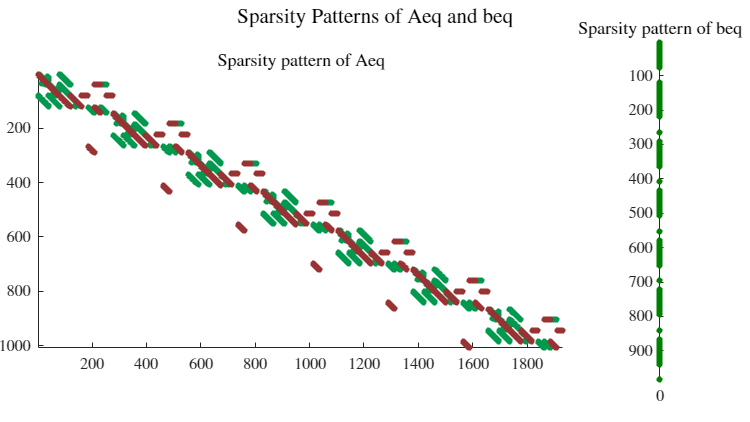


ans = 

  Map with properties:

        Count: 0
      KeyType: char
    ValueType: any



% for t = 1:T
    if logging && verbose
        error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
    elseif logging && ~verbose
        fileOpenedFlag = true;
        % if t == 1
            fid = fopen(saveLocationFilename, 'w');
        % else
            % fid = fopen(saveLocationFilename, 'a');
        % end
    elseif ~logging
        logging = verbose;
        fid = 1;
    end
    
    % if t == 1
        myfprintf(logging, fid, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
    "will be run.\n", T, delta_t*60, delta_t*T);
    % end

    myfprintf(logging, fid, "********Running Full OPF for the system.********\n"); %always true
    keepRunningIterations = true;
    macroItr = 1;
    time_dist = zeros(macroItrMax, numAreas);
    macroIterationPLosses = zeros(macroItrMax, numAreas);
    macroIterationQLosses = zeros(macroItrMax, numAreas);
    macroIterationPSaves = zeros(macroItrMax, numAreas);
    ResidualMax = zeros(macroItrMax, 1);
    v2_parent = 1.03^2*ones(numAreas, 1);
    % lambdaVal = lambdaVals(t);
    % pvCoeff = pvCoeffVals(t);
    Se_iter = zeros(macroItrMax, numAreas);
    V_iter = zeros(macroItrMax, N, numUniqueParents);
    S_allRelationships = CBTable.S_childArea;
    S_parent = zeros(numAreas, 1);
    S_Areas = zeros(N, numAreas);
    v2_Areas = zeros(N, numAreas);
    
    t = 1;
    while keepRunningIterations
        for Area = 1:numAreas
            
            v2_parent_Area = v2_parent(Area);
            S_childAreas = S_allRelationships(CBTable.parentArea == Area);
    
            isLeaf_Area = isLeaf(Area);
            isRoot_Area = isRoot(Area);
            numChildAreas_Area = numChildAreas(Area);
            
            B0Vals_pu_Area = B_j_pu(t, Area, :);
    
            [xVals_Area, B0Vals_pu_Area, ...
                macroIterationPLosses, macroIterationQLosses, ...
                macroIterationPSaves, macroItr, time_dist, ...
                N_Area, m_Area, nDER_Area, nBatt_Area, ...
                busDataTable_Area, branchDataTable_Area] = ...
                ...
                NL_OPF_dist2(v2_parent_Area, S_childAreas, B0Vals_pu_Area, ...
                lambdaVals, pvCoeffVals, ...
                Area, isLeaf_Area, isRoot_Area, numChildAreas_Area, numAreas, ...
                macroIterationPLosses, macroIterationQLosses, ...
                macroIterationPSaves, ...
                macroItr, time_dist, t, T,   ...
                CBTable, 'verbose', verbose, 'saveToFile', true, 'logging', logging);
            
            N_Areas(Area) = N_Area;
            m_Areas(Area) = m_Area;
            nDER_Areas(Area) = nDER_Area;
            nBatt_Areas(Area) = nBatt_Area;

            numVarsFull = [m_Area, m_Area, m_Area, N_Area, nDER_Area, nBatt_Area, nBatt_Area, nBatt_Area, nBatt_Area];
            ranges_Full = generateRangesFromValues(numVarsFull);

            indices_P = ranges_Full{1};
            indices_Q = ranges_Full{2};
            indices_l = ranges_Full{3};
            indices_vAll = ranges_Full{4};
            indices_v = indices_vAll(2:end);
            indices_qD = ranges_Full{5};
            indices_B = ranges_Full{6};
            indices_Pc = ranges_Full{7};
            indices_Pd = ranges_Full{8};
            indices_qB = ranges_Full{9};
            
            P_Area = xVals_Area(indices_P); %m_Areax1
            Q_Area = xVals_Area(indices_Q); %m_Areax1
            S_Area = complex(P_Area, Q_Area); %m_Areax1
            l_Area = xVals_Area(indices_l);
            vFull_Area = xVals_Area(indices_vAll); %N_Areax1
            v2_Area = vFull_Area;
            qD_Area = xVals_Area(indices_qD);
            B_Area = xVals_Area(indices_B);
            Pd_Area = xVals_Area(indices_Pd);
            Pc_Area = xVals_Area(indices_Pc);
            qB_Area = xVals_Area(indices_qB);

            % P_ij(t, Area, 1:m_Area) = P_Area;
            % Q_ij(t, Area, 1:m_Area) = Q_Area; %m_Areax1
            % S_ij(t, Area, 1:m_Area) = complex(P_Area, Q_Area); %m_Areax1
            % l_ij(t, Area, 1:m_Area) = l_Area;
            % v_j(t, Area, 1:N_Area) = vFull_Area;
            % qD_j(t, Area, 1:nDER_Area) = qD_Area;
            % B_j_pu(t, Area, 1:nBatt_Area) = B0Vals_pu_Area;

            % P_der_BusesWithBatts = busDataTable_Area(busDataTable_Area.P_der ~= 0, :).P_der;
            % B_j(t, Area, 1:nBatt_Area) = 100*B0Vals_pu_Area./(chargeToPowerRatio * P_der_BusesWithBatts);
            % B_j_pu(t+1, Area, 1:nBatt_Area) = B_Area;
            % B_j(t+1, Area, 1:nBatt_Area) = 100*B_Area./(chargeToPowerRatio * P_der_BusesWithBatts);
            % Pc_j_pu(t, Area, 1:nBatt_Area) = Pc_Area;
            % Pc_j(t, Area, 1:nBatt_Area) = Pc_Area * kVA_B;
            % Pd_j_pu(t, Area, 1:nBatt_Area) = Pd_Area;
            % Pd_j(t, Area, 1:nBatt_Area) = Pd_Area * kVA_B;
            % qB_j(t, Area, 1:nBatt_Area) = qB_Area;

            
            S_parent(Area) = S_Area(1);
            
            v2_Areas(1:N_Area, Area) = vFull_Area;
            S_Areas(1:m_Area, Area) = S_Area;   % Storing all the S flow of the Area
    
        end
        
        
        for relationshipNum = 1 : numRelationships
    
            parAr = CBTable.parentArea(relationshipNum);
            chAr = CBTable.childArea(relationshipNum);
            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            S12_fromParent = S_Areas(parentAreaConnectingBus - 1, parAr);
            S12_intoChild = S_parent(chAr);
    
            delta_S12 = S12_fromParent - S12_intoChild;
    
            v2_parentSide = v2_Areas(parentAreaConnectingBus, parAr);
            v2_childSide = v2_parent(chAr);
    
            delta_v2 = v2_parentSide - v2_childSide;
    
            Residual_Area = [delta_S12; delta_v2];
            
            if max(abs(Residual_Area)) > ResidualMax(macroItr+1)
                ResidualMax(macroItr+1) = max(abs(Residual_Area));
            end
    
        end
        
        if macroItr > macroItrMax
            % keepRunningIterations = false;
            error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
    
        elseif ResidualMax(macroItr+1) < tol
            myfprintf(logging, fid, "Time Period = %d, Converged in %d macro-iterations!\n", t, macroItr);
            keepRunningIterations = false;
            ResidualMax = ResidualMax(1:macroItr);
    
        else
            myfprintf(logging, fid, "Time Period = %d, Still yet to converge after %d macro-iterations, continuing.\n", t, macroItr)
            %Communication-
            
            for relationshipNum = 1:numRelationships
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                busParTo = CBTable.conBus_parentAreaTo(relationshipNum);
                V_iter(macroItr+1, busParTo, parAr) = v2_Areas(busParTo, parAr) ;
                Se_iter(macroItr+1,chAr) = S_parent(chAr);
    
                if macroItr > 2
                    v2_parent(chAr) = a(2)*V_iter(macroItr-1, busParTo, parAr)+...
                        a(1)*V_iter(macroItr, busParTo, parAr)+...
                        (1-sum(a))*v2_Areas(busParTo, parAr) ;
    
                    S_allRelationships(relationshipNum) = a(2)*Se_iter(macroItr-1, chAr)+...
                        a(1)*Se_iter(macroItr, chAr)+...
                        (1-sum(a))*S_parent(chAr);
                else
    
                    v2_parent(chAr) = v2_Areas(busParTo, parAr);
                    S_allRelationships(relationshipNum) = S_parent(chAr);
    
                end
    
            end
    
            macroItr = macroItr + 1;
    
        end
         
        % S12 = transpose(S_Areas(1, :));
        % P12s(t, :) = kVA_B*real(S12);
        % Q12s(t, :) = kVA_B*imag(S12);
        % V1s(t, :) = sqrt(transpose(v2_Areas(1, :)));
        % PSaves(t, :) = macroIterationPSaves(macroItr, :);
    
    end

    
    N_ParentArea_Max = max(N_Areas(uniqueParents));
    Se_iter = Se_iter(1:macroItr, :);
    V_iter = V_iter(1:macroItr, 1:N_ParentArea_Max, uniqueParents);
    
    macroIterationPLosses = macroIterationPLosses(1:macroItr, :);
    macroIterationQLosses = macroIterationQLosses(1:macroItr, :);
    time_dist = time_dist(1:macroItr, :);
    
    % PLosses(t) = kVA_B * sum(macroIterationPLosses(macroItr, :)); %sum over each row
    % QLosses(t) = kVA_B * sum(macroIterationQLosses(macroItr, :));
    % PSubs(t) = P12s(t, 1);
    % QSubs(t) = Q12s(t, 1);
    % solutionTimes(t) = sum(time_dist(macroItr, :));

    % postProcessResults(T, N, numAreas, N_Areas, isRoot, v2_Areas, actualBusNums, ...
    %     macroIterationPLosses, t, macroItr, time_dist, kVA_B, displaySimulationResultPlots, ...
    %     ResidualMax, saveSimulationResultPlots, systemName, S_Areas, start, generateTextFilesForResults);

% end

if fileOpenedFlag
    fclose(fid);
end
grandTotalTime = toc(start)


% % Create a cell array containing the names of the structures
% tableNames = {'xSys', 'ySys', 'yArs', 'yNodes'};
% 
% % Loop through each structure
% for structIndex = 1:length(tableNames)
%     structName = tableNames{structIndex};
%     currentStruct = eval(structName); % Access the structure by its name
% 
%     % Loop through each variable name in the 'VarNames' field
%     for varIndex = 1:length(currentStruct.VarNames)
%         varName = currentStruct.VarNames{varIndex}; % Get the variable name
% 
%         % Use eval to get the value of the variable whose name is stored in varName
%         % and assign it to the 'Vars' field in the current structure
%         currentStruct.Vars{varIndex} = eval(varName);
%     end
% 
%     % Assign the modified structure back to its original variable name
%     eval([structName, ' = currentStruct;']);
% end



% results = struct();
% results.xSys = xSys;
% results.ySys = ySys;
% results.yArs = yArs;
% results.yNodes = yNodes;
% results.objFun = strObjectiveFunction;
% results.suffixObj = suffixObj;


plotSimulationResults(results, 'verbose', true);